# MA 423 Matrix Computations                    Lab - 9

## Name: Rasesh Srivastava

## Roll number: 210123072

format long e

## Question 2

x = [1 1 1]';
array = zeros(3, 3, 3);
array(:, :, 1) = [1 1 1; -1 9 2; 0 -1 2];
array(:, :, 2) = [1 1 1; -1 9 2; -4 -1 2];
array(:, :, 3) = [1 1 1; -1 3 2; -4 -1 2];

#### Part (i)

A = array(:, :, 1);
[iter, lambda] = Powermethod(A, x, 15);
[V, D] = eig(A, 'vector');
[D, I] = sort(D, 'descend');
V = V(:, I);
[lambda_1, lambda_2] = deal(D(1), D(2));
theoretical_rate = abs(lambda_2) / abs(lambda_1);
[val, idx] = max(abs(V(:, 1)));
v = V(:, 1);
v = v / v(idx);
experimental_rate = norm(iter(:, end) - v) / norm(iter(:, end - 1) - v);

Theoretical rate of convergence

theoretical_rate

theoretical_rate =      2.556817793836642e-01


Experimental rate of convergence

experimental_rate

experimental_rate =      2.556807173384127e-01


Theoretical eigen vector

v

v =      1.118247135983154e-01
     1.000000000000000e+00
    -1.518734730355965e-01


Experimental eigen vector

iter(:, end)

ans =      1.118247144719848e-01
     1.000000000000000e+00
    -1.518734718167874e-01


#### Part (ii)

A = array(:, :, 2);
[iter, lambda] = Powermethod(A, x, 15);
[V, D] = eig(A, 'vector');
[D, I] = sort(D, 'descend');
V = V(:, I);
[lambda_1, lambda_2] = deal(D(1), D(2));
theoretical_rate = abs(lambda_2) / abs(lambda_1);
[val, idx] = max(abs(V(:, 1)));
v = V(:, 1);
v = v / v(idx);
experimental_rate = norm(iter(:, end) - v) / norm(iter(:, end - 1) - v);

Theoretical rate of convergence

theoretical_rate

theoretical_rate =      2.904339802659630e-01


Experimental rate of convergence

experimental_rate

experimental_rate =      4.392569415944970e-01


Theoretical eigen vector

v

v =      1.046506193465949e-01
     1.000000000000000e+00
    -2.197382946062937e-01


Experimental eigen vector

iter(:, end)

ans =      1.046506211209667e-01
     1.000000000000000e+00
    -2.197382774530076e-01


#### Part (iii)

A = array(:, :, 3);
[iter, lambda] = Powermethod(A, x, 15);
[V, D] = eig(A, 'vector');
[D, I] = sort(D, 'descend');
V = V(:, I);
[lambda_1, lambda_2] = deal(D(1), D(2));
theoretical_rate = abs(lambda_2) / abs(lambda_1);
[val, idx] = max(abs(V(:, 1)));
v = V(:, 1);
v = v / v(idx);
experimental_rate = norm(iter(:, end) - v) / norm(iter(:, end - 1) - v);

Theoretical rate of convergence

theoretical_rate

theoretical_rate =      1


Experimental rate of convergence

experimental_rate

experimental_rate =      1.602716382132409e+00


Theoretical eigen vector

v

v =      -8.756926762599568e-02 - 4.301608749736983e-01i
     -2.978913837372592e-02 - 8.157616273260181e-01i
      1.000000000000000e+00 + 0.000000000000000e+00i


Experimental eigen vector

iter(:, end)

ans =      4.737094380293395e-01
     1.000000000000000e+00
     7.459198017678873e-01


The table contains the eigen values of all the matrices such that |λ1| >= |λ2| >= |λ3|. 

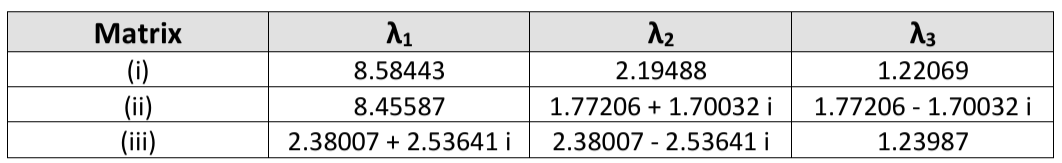

In case (i), we can observe that it is a strict inequality. Hence, the convergence happens in this case and experimental rate is same as the theoretical rate.

In case (ii), we have a dominant eigen value, but |λ2| = |λ3|. Hence, the convergence happens but the experimental rate is slower than the theoretical rate.

In case (iii), we do not have a dominant eigen value. Hence, the Power method fails to converge in this case and we observe such a behaviour while calculating the rate of convergence

## Question 3

k = 10;

#### Part (i)

A = [1 1 1; -1 9 2; 0 -1 2];
[V, ~] = eig(A);
x = V(:,2)+V(:,3);
check_convergence(A, x, k);

     8.581364932655978e-01



### Part (ii)

A = [1 1 1; -1 9 2; -4 -1 2];
[V, ~] = eig(A);
x = V(:,2)+V(:,3);
check_convergence(A, x, k);

     4.851843778297393e-06



### Part (iii)

A = [1 1 1; -1 3 2; -4 -1 2];
[V, ~] = eig(A);
x = V(:,2)+V(:,3);
check_convergence(A, x, k);

     4.602018996435753e-05



An important necessary condition for the iterations to converge is violated and hence, the iterations of the Power Method are not converging.

## Question 4

x = ones(3, 1);
k = 10;
s = 5;
A = [1 1 1; -1 9 2; 0 -1 2];
[iter, lambda] = Shiftinv(A, x, s, k);
[V, D] = eig(A);
[~,indx] = max(abs(diag(D)));
norm(iter(:,end) - V(:,indx))

ans =      1.688381017159951e+00


norm(lambda - D(indx, indx))

ans =      6.477932174154914e+00


## Question 7

A1 = [1 1 1; -1 9 2; 0 -1 2];
A2 = [1 1 1; -1 9 2; -4 -1 2];
A3 = [1 1 1; -1 3 2; -4 -1 2];
tol = 1e-6;
x = [1; 1; 1];
k = 20;

[iter1_pm, lambda1_pm] = Powermethod(A1, x, k);
[iter2_pm, lambda2_pm] = Powermethod(A2, x, k);
[iter3_pm, lambda3_pm] = Powermethod(A3, x, k);
conv_rate_pm1 = compute_convergence_rate(iter1_pm, tol);
conv_rate_pm2 = compute_convergence_rate(iter2_pm, tol);
conv_rate_pm3 = compute_convergence_rate(iter3_pm, tol);

s1 = 2;
[iter1_si, lambda1_si] = Shiftinv(A1, x, s1, k);
s2 = 3;
[iter2_si, lambda2_si] = Shiftinv(A2, x, s2, k);
s3 = 1;
[iter3_si, lambda3_si] = Shiftinv(A3, x, s3, k);
conv_rate_si1 = compute_convergence_rate(iter1_si, tol);
conv_rate_si2 = compute_convergence_rate(iter2_si, tol);
conv_rate_si3 = compute_convergence_rate(iter3_si, tol);

[iter1_rq, lambda1_rq] = Rayleigh(A1, x, k);
[iter2_rq, lambda2_rq] = Rayleigh(A2, x, k);
% [iter3_rq, lambda3_rq] = Rayleigh(A3, x, k);
conv_rate_rq1 = compute_convergence_rate(iter1_rq, tol);
conv_rate_rq2 = compute_convergence_rate(iter2_rq, tol);
% conv_rate_rq3 = compute_convergence_rate(iter3_rq, tol);

fprintf('Results for A1:\n');

Results for A1:


fprintf('Power Method Eigenvalue: %.6e, Convergence Rate: %.6e\n', lambda1_pm, conv_rate_pm1);

Power Method Eigenvalue: 8.584428e+00, Convergence Rate: 4.770123e-12


fprintf('Shift-Invert Method Eigenvalue: %.6e, Convergence Rate: %.6e (Shift: %f)\n', lambda1_si, conv_rate_si1, s1);

Shift-Invert Method Eigenvalue: 2.194882e+00, Convergence Rate: 2.520735e-13 (Shift: 2.000000)


fprintf('Rayleigh Quotient Method Eigenvalue: %.6e, Convergence Rate: %.6e\n\n', lambda1_rq, conv_rate_rq1);

Rayleigh Quotient Method Eigenvalue: 2.194882e+00, Convergence Rate: 0.000000e+00



fprintf('Results for A2:\n');

Results for A2:


fprintf('Power Method Eigenvalue: %.6e, Convergence Rate: %.6e\n', lambda2_pm, conv_rate_pm2);

Power Method Eigenvalue: 8.455873e+00, Convergence Rate: 8.980495e-11


fprintf('Shift-Invert Method Eigenvalue: %.6e, Convergence Rate: %.6e (Shift: %f)\n', lambda2_si, conv_rate_si2, s2);

Shift-Invert Method Eigenvalue: -1.145040e+00, Convergence Rate: Inf (Shift: 3.000000)


fprintf('Rayleigh Quotient Method Eigenvalue: %.6e, Convergence Rate: %.6e\n\n', lambda2_rq, conv_rate_rq2);

Rayleigh Quotient Method Eigenvalue: 8.455873e+00, Convergence Rate: 0.000000e+00



fprintf('Results for A3:\n');

Results for A3:


fprintf('Power Method Eigenvalue: %.6e, Convergence Rate: %.6e\n', lambda3_pm, conv_rate_pm3);

Power Method Eigenvalue: 3.593669e+00, Convergence Rate: Inf


fprintf('Shift-Invert Method Eigenvalue: %.6e, Convergence Rate: %.6e (Shift: %f)\n', lambda3_si, conv_rate_si3, s3);

Shift-Invert Method Eigenvalue: 1.239868e+00, Convergence Rate: 0.000000e+00 (Shift: 1.000000)


% fprintf('Rayleigh Quotient Method Eigenvalue: %.6e, Convergence Rate: %.6e\n\n', lambda3_rq, conv_rate_rq3);

Analysis of Convergence:

We can observe the convergence rates for each method. Lower values indicate faster convergence. We can notice how the shifting strategies used in the Shift and Invert and Rayleigh Quotient Methods accelerate the convergence in comparison to Power Method.

# Function Programs

## Question 1

function [iter, lambda] = Powermethod(A, x, k)
    iter = [x / max(abs(x))];
    for j = 1 : k
       q = A * iter(:, end);
       [~, idx] = max(abs(q));
       scaling_factor = q(idx);
       q = q / scaling_factor;
       iter(:, end + 1) = q;
    end
    lambda = scaling_factor;
end

## Question 3

function check_convergence(A, x, k)
    [V, D] = eig(A);
    v = V(:,1);
    theoretical_conv = abs(D(2, 2))/abs(D(1, 1));
    [iter, ~] = Powermethod(A, x, k);
    actual_conv = norm(iter(:,end)-v)/norm(iter(:,end-1)-v);
    disp([norm(actual_conv - theoretical_conv)]);
end

## Question 4

function x = rowforward(L,b)
    n = size(b, 1);
    x = zeros(n, 1);
    for i = 1:n
        if L(i, i) == 0
            error('Provided L is singular');
        end
        x(i) = (b(i) - L(i, 1:i-1)*x(1:i-1)) / L(i, i);
    end
end

function x = colbackward(U,b)
    n = size(b, 1);
    x = zeros(n, 1);
    for i = n:-1:1
        if U(i, i) == 0
            error('Provided U is singular');
        end
        x(i) = b(i) / U(i, i);
        b(1 : i - 1) = b(1 : i - 1) - U(1 : i-1, i)*x(i);
    end
end

function [iter, lambda] = Shiftinv(A, x, s, k)
    [n, ~] = size(A);
    A_prime = A - s * eye(n);
    [L, U, P] = lu(A_prime);
    iter = [x / max(abs(x))];
    for j = 1 : k
       b = P * iter(:, end);
       y = rowforward(L, b);
       q = colbackward(U, y);
       [~, idx] = max(abs(q));
       scaling_factor = q(idx);
       q = q / scaling_factor;
       iter(:, end + 1) = q;
    end
    lambda = s + 1/scaling_factor;
end

## Question 5

function [L, U, p] = gepphess(A)
    n = size(A, 1);
    p = 1:n;
    L = eye(n);
    for k = 1:n-1
        [~, maxIndex] = max(abs(A(k:n, k)));
        maxIndex = maxIndex + k - 1;
        if maxIndex ~= k
            A([k, maxIndex], :) = A([maxIndex, k], :);
            p([k, maxIndex]) = p([maxIndex, k]);
            if k > 1
                L([k, maxIndex], 1:k-1) = L([maxIndex, k], 1:k-1);
            end
        end
        for j = k+1:n
            L(j, k) = A(j, k) / A(k, k);
            A(j, k:n) = A(j, k:n) - L(j, k) * A(k, k:n);
        end
    end
    U = A;
end

## Question 6

function [iter, lambda] = Rayleigh(A, x, k)
    [n, ~] = size(A);
    [~, H] = hess(A);
    [~, idx] = max(abs(x));
    iter = [x / x(idx)];
    q0 = iter(:, 1);
    rho = q0' * H * q0 / (q0' * q0);
    for j = 1 : k
        A_prime = H - rho * eye(n);
        [L, U, P] = lu(A_prime); 
        % [L, U, P] = gepphess(A_prime);
        b = P * iter(:, end);
        y = rowforward(L, b);
        q = colbackward(U, y);
        [~, idx] = max(abs(q));
        scaling_factor = q(idx);
        q = q / scaling_factor;
        iter(:, end + 1) = q;
        rho = q' * H * q / (q' * q);
    end
    lambda = rho;
end

## Question 7

function conv_rate = compute_convergence_rate(iter, tol)
    n_iter = size(iter, 2);
    conv_rate = inf;
    for j = 2:n_iter
        diff = norm(iter(:, j) - iter(:, j - 1));
        if diff < tol
            conv_rate = min(conv_rate, diff);
        end
    end
end